# Numerical Analysis Homework - Derivatives

## Maxwell Greene

Using the segmentation method to find the derivative. 

## Question #1:

Write a program to find $f'(x)
$ at $x$ and plot.

len = 1001;
x = linspace(0,4*pi,len);
h = x(2)-x(1);
f = @(x) sin(pi/2*x)

f = function_handle with value:
    @(x)sin(pi/2*x)


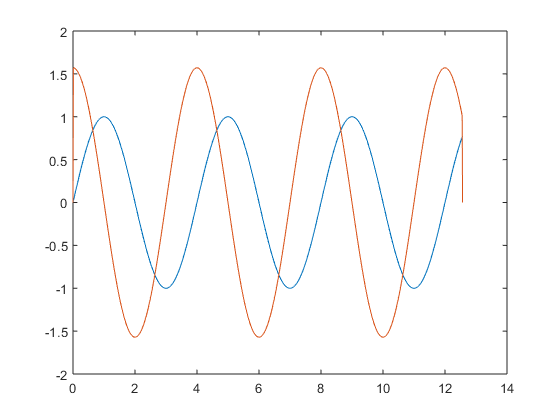

y = f(x);
yP = zeros(1,len);
for i = 2:(len-1)
    yP(i) = (y(i+1)-y(i-1))/(2*h);
end
plot(x,y,x,yP)

## Question #2: 

Find f'' for the following:

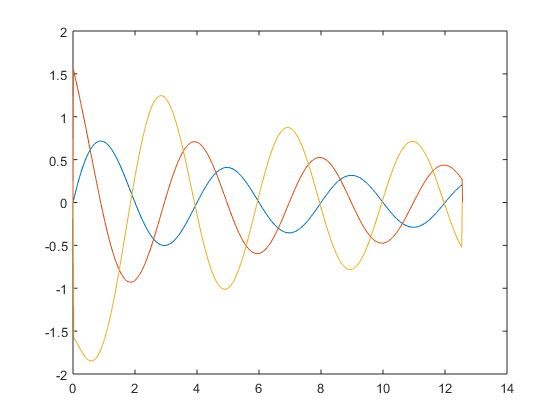

clear all
len = 1001;
x = linspace(0,4*pi,len);
h = x(2)-x(1);
f = @(x) sin(pi/2*x)./sqrt(x+1);
y = f(x);
yP = zeros(1,len);
for i = 2:(len-1)
    yP(i) = (y(i+1)-y(i-1))/(2*h);
end
yPP = zeros(1,len);
for i = 2:(len-1)
    yPP(i) = (yP(i+1)-yP(i-1))/(2*h);
end
for i = 1:len
    if (abs(yPP(i))>10) yPP(i)=0; end
end

plot(x,y,x,yP,x,yPP)